data = readtable("hr", 'Format', "%s", 'ReadVariablenames', false);

ir_vals = [];
red_vals = [];
sound_vals = [];

% skip first row
for i=2:length(data.Var1)
    num = regexp(data.Var1(i), "-?\d*", 'match');
    num = str2double(num{1,1});
    if ~isnan(num)
        if contains(data.Var1(i), "IR VAL:")
            ir_vals = [ir_vals, num];
        elseif contains(data.Var1(i), "RED VAL:")
            red_vals = [red_vals, num];
        else
            sound_vals = [sound_vals, num];
        end
    end
end

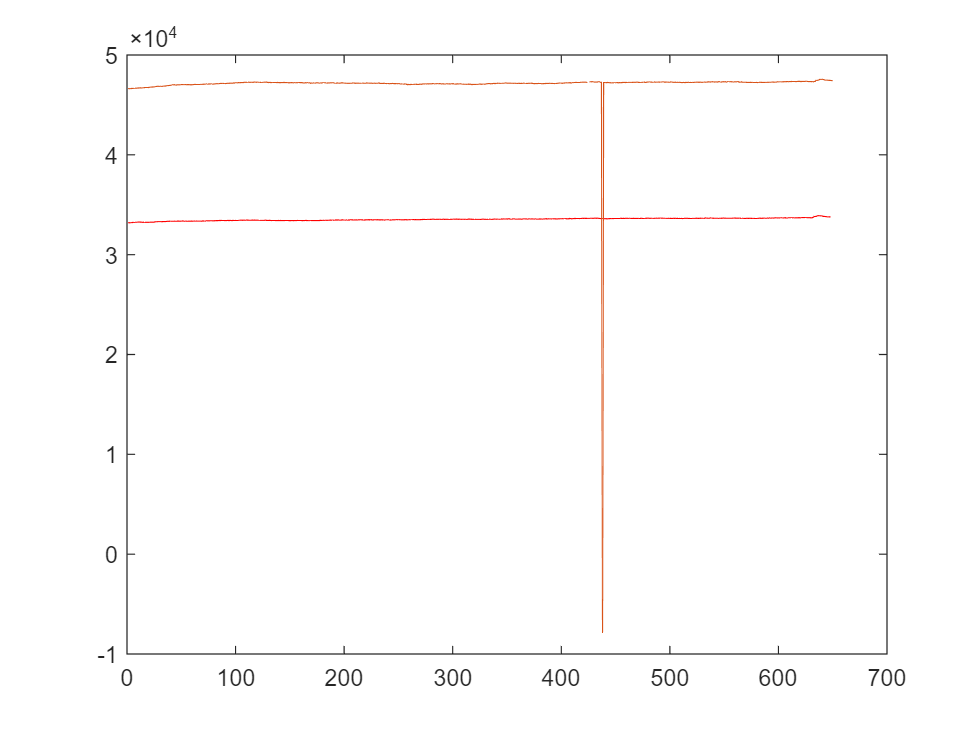

plot(red_vals, 'Color', 'red')
hold on
plot(ir_vals)
hold off

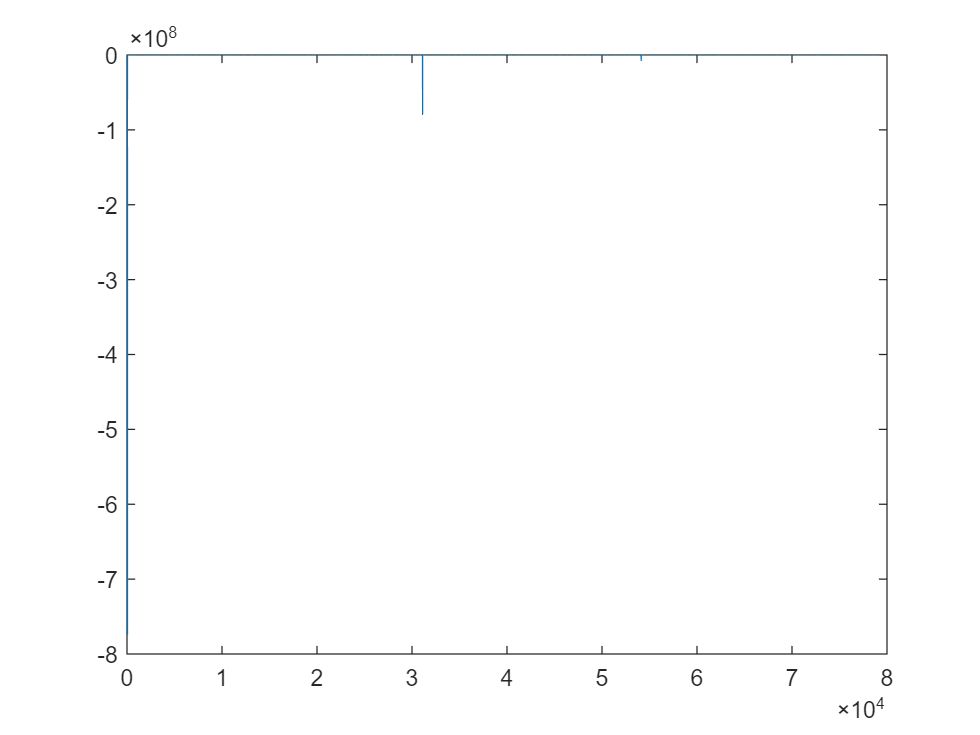


plot(sound_vals)